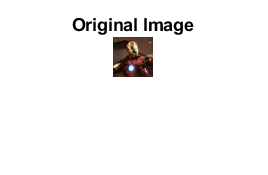

clc;
clear;
close all;

%% =========================
% 1. LOAD IMAGE
%% =========================
img = imread('ironman.png'); 

figure;
imshow(img);
title('Original Image');

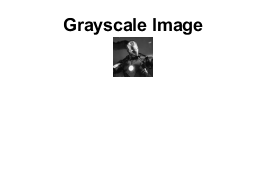


%% =========================
% 2. CONVERT TO GRAYSCALE
%% =========================
gray_img = rgb2gray(img);

figure;
imshow(gray_img);
title('Grayscale Image');

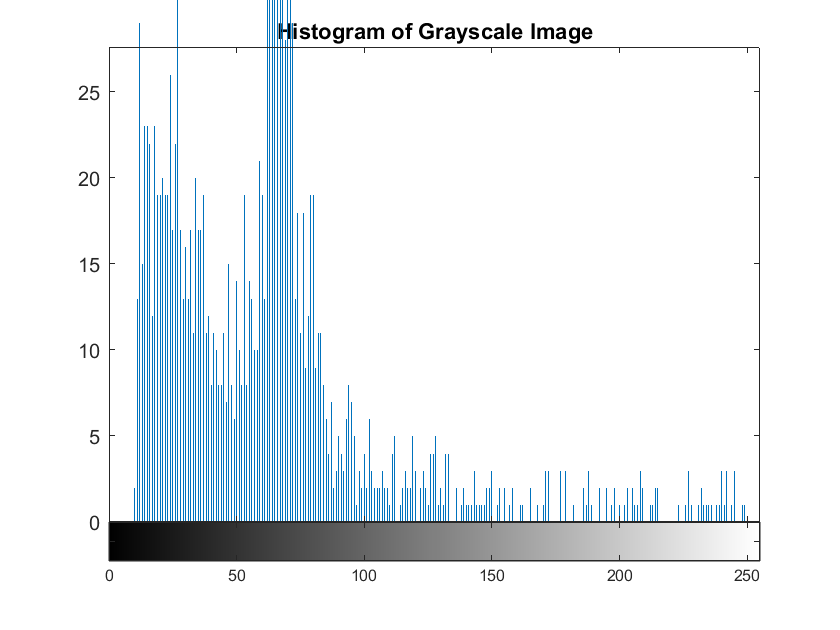


%% =========================
% 3. DISPLAY HISTOGRAM
%% =========================
figure;
imhist(gray_img);
title('Histogram of Grayscale Image');


%% =========================
% 4. ANALYZE INTENSITY (BRIGHTNESS)
%% =========================

% Compute basic statistics
mean_intensity = mean(gray_img(:));
min_intensity = min(gray_img(:));
max_intensity = max(gray_img(:));

%% Display results in command window
disp('--- Image Intensity Analysis ---');

--- Image Intensity Analysis ---


fprintf('Mean Brightness: %.2f\n', mean_intensity);

Mean Brightness: 63.41


fprintf('Minimum Intensity: %d\n', min_intensity);

Minimum Intensity: 10


fprintf('Maximum Intensity: %d\n', max_intensity);

Maximum Intensity: 249


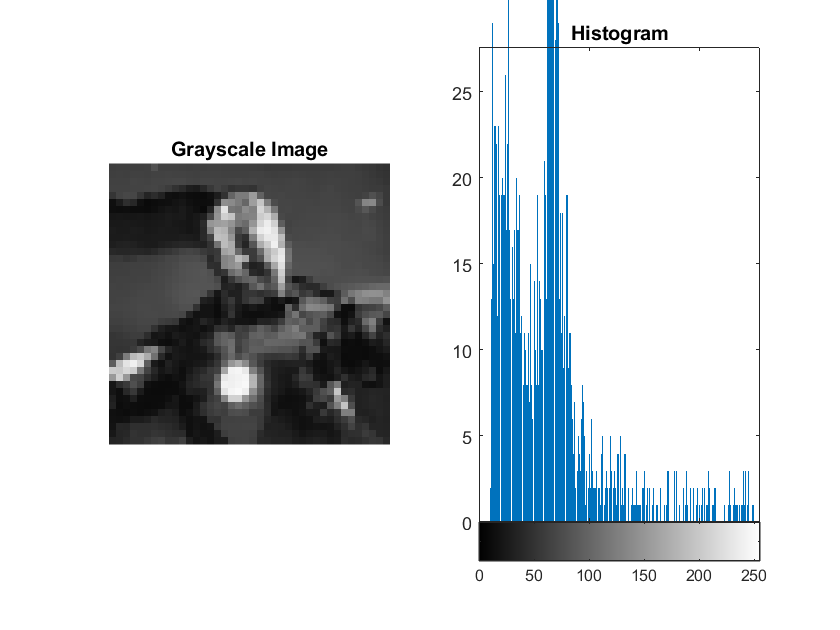


%% =========================
% 5. OPTIONAL: ENHANCED VISUAL COMPARISON
%% =========================
figure;

subplot(1,2,1);
imshow(gray_img);
title('Grayscale Image');

subplot(1,2,2);
imhist(gray_img);
title('Histogram');